# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.6 特殊绘图

#### 2.6.2 Newton-Raphson、Julia分形

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)

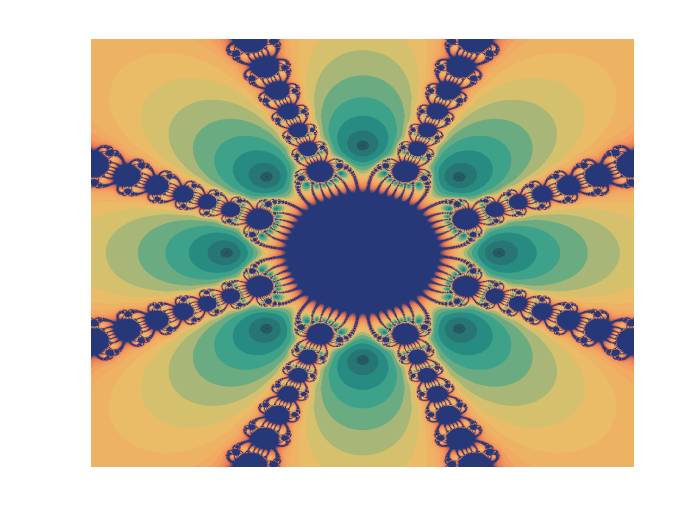

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors();
% 创建 colormap
map = GenColormap(all_themes{2}, 64);
n = 1000;
m = 1000;
f = @(z) z^8 - 1;
df = @(z) 8*z^7;
[X, Y] = meshgrid(linspace(-2, 2, n), linspace(-2, 2, m));
A = nan(n, m);
for i = 1:n
    for j = 1:m
        z0 = X(i, j) + 1i*Y(i, j);
        % Newton-Raphson
        z = z0;
        ite = 0;
        fz = f(z);
        while abs(fz) > 1e-6 && ite < 20
            z = z - f(z)/df(z); 
            fz = f(z);
            ite = ite + 1;
        end
        A(i, j) = ite;
    end
end
figure;
pcolor(X, Y, A);
colormap(map);
% hold on
% plot([1, -1, 0, 0], [0, 0, 1, -1], '.k', 'MarkerSize', 20);
% hold off
shading flat
axis tight manual off

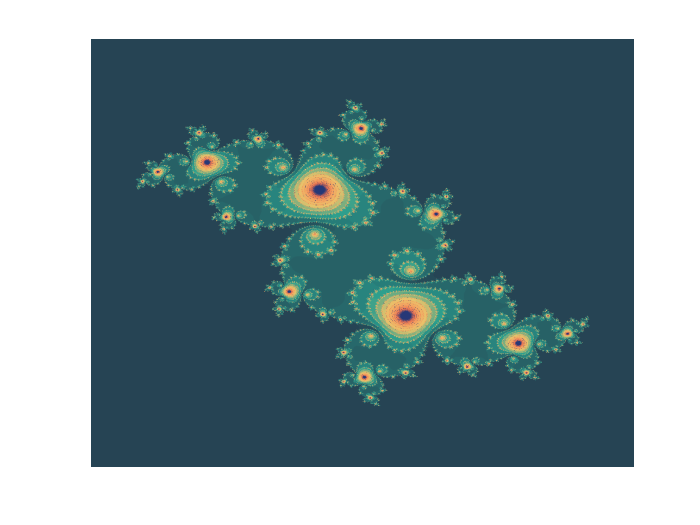

% xlim([-0.5, 0]);
% ylim([0.5, 1]);
% 保存成视频
% set(gca, 'nextplot', 'replacechildren'); 
% v = VideoWriter('NRfractal.avi');
% open(v);
% for k = 1:20 
%     pcolor(X, Y, A);
%     shading flat
%     xlim([-2*(1-k/25), 2*(1-k/25)]);
%     ylim([-2*(1-k/25), 2*(1-k/25)]);
%     frame = getframe(gcf);
%     writeVideo(v, frame);
% end

% (-0.19, 0.6557)
% (-0.1, 0.651)
% zx = zx*zx - zy*zy + cx
% zy = 2*zx*zy+cy
c = - 0.1 + 1i*0.651;
radius = 32;
[X, Y] = meshgrid(linspace(-1.5, 1.5, n), linspace(-1.5, 1.5, m));
A = nan(n, m);
for i = 1:n
    for j = 1:m
        z = X(i, j) + 1i*Y(i, j);
        % Julia
        for ite = 1:1000
            z = (z*z + c) ;
            if abs(z) > radius
                break;
            end
        end
        A(i, j) = ite;
    end
end
figure;
pcolor(X, Y, A);
colormap(map);
shading flat
axis tight manual off